clc;
clear;

const_x=2;   %desplazamiento en metros de trackable1
const_y=0;
const_z=0;


folder = uigetdir();
fileList = dir(fullfile(folder, '*.csv'));
fileList = {fileList.name};
fileList

fileList = 1×2 cell array
    {'_slash_pozyx_coords.csv'}    {'_slash_tf.csv'}



pozyx_data = readtable(string(fileList(1)));
tf_data = readtable(string(fileList(2)), 'PreserveVariableNames', true);
tf_data

tf_data = 23049×104 table
         rosbagTimestamp         transforms    header    seq    stamp       secs         nsecs                    frame_id                                  child_frame_id                      transform    translation       x          y          z        rotation    x_1     y_1         z_1          w        Var20    Var21    Var22      Var23         Var24                      Var25                              Var26                Var27    Var28    Var29     Var30


pozyx.time=pozyx_data.rosbagTimestamp;
pozyx.position.x= pozyx_data.x/1000;
pozyx.position.y= pozyx_data.y/1000;
pozyx.position.z= pozyx_data.z/1000;

pozyx.time(pozyx.position.x==0) = [];
pozyx.position.x(pozyx.position.x==0) = [];
pozyx.position.y(pozyx.position.y==0) = [];
pozyx.position.z(pozyx.position.z==0) = [];


tf_foot_odom.position.x= [];
tf_foot_odom.position.y= [];
tf_foot_odom.position.z= [];
tf_foot_odom.orientation.x= [];
tf_foot_odom.orientation.y= [];
tf_foot_odom.orientation.z= [];
tf_foot_odom.orientation.w= [];


tf_odom_map.position.x= [];
tf_odom_map.position.y= [];
tf_odom_map.position.z= [];
tf_odom_map.orientation.x= [];
tf_odom_map.orientation.y= [];
tf_odom_map.orientation.z= [];
tf_odom_map.orientation.w= [];

tf_compare.time_s=tf_data.secs;
tf_compare.time_ns=tf_data.nsecs;
tf_compare.frame_id = tf_data.frame_id;
tf_compare.child_frame_id = tf_data.child_frame_id;
tf_compare.position.x= tf_data.x;
tf_compare.position.y= tf_data.y;
tf_compare.position.z= tf_data.z;
tf_compare.orientation.x= tf_data.x_1;
tf_compare.orientation.y= tf_data.y_1;
tf_compare.orientation.z= tf_data.z_1;
tf_compare.orientation.w= tf_data.w;

%-------------------------------------------------------------------------------
%Filtrado de las tablas para quedarnos con las 2 transformadas que nos interesan
%-------------------------------------------------------------------------------
j=1;
k=1;
index_child_id_odom = find(strcmp(tf_compare.child_frame_id, '"robot_odom"'));

for i=1:size(index_child_id_odom,1)
    if (strcmp(tf_compare.frame_id{index_child_id_odom(i)}, '"robot_map"'))
        tf_odom_map.time_s(k,1) = tf_compare.time_s(i);
        tf_odom_map.time_ns(k,1) = tf_compare.time_ns(i);
        tf_odom_map.child_frame_id{k,1} = '"robot_odom"';
        tf_odom_map.frame_id{k,1} = '"robot_map"';
        tf_odom_map.position.x(k,1) = tf_compare.position.x(index_child_id_odom(i));
        tf_odom_map.position.y(k,1) = tf_compare.position.y(index_child_id_odom(i));
        tf_odom_map.position.z(k,1) = tf_compare.position.z(index_child_id_odom(i));
        tf_odom_map.orientation.x(k,1) = tf_compare.orientation.x(index_child_id_odom(i));
        tf_odom_map.orientation.y(k,1) = tf_compare.orientation.y(index_child_id_odom(i));
        tf_odom_map.orientation.z(k,1) = tf_compare.orientation.z(index_child_id_odom(i));
        tf_odom_map.orientation.w(k,1) = tf_compare.orientation.w(index_child_id_odom(i));


        for j=1:3
            if (strcmp(tf_compare.child_frame_id{index_child_id_odom(i)+j}, '"robot_base_footprint"'))
                tf_foot_odom.time_s(k,1) = tf_compare.time_s(index_child_id_odom(i)+j);
                tf_foot_odom.time_ns(k,1) = tf_compare.time_ns(index_child_id_odom(i)+j);
                tf_foot_odom.child_frame_id{k,1} = '"robot_base_footprint"';
                tf_foot_odom.frame_id{k,1} = '"robot_odom"';
                tf_foot_odom.position.x(k,1) = tf_compare.position.x(index_child_id_odom(i)+j);
                tf_foot_odom.position.y(k,1) = tf_compare.position.y(index_child_id_odom(i)+j);
                tf_foot_odom.position.z(k,1) = tf_compare.position.z(index_child_id_odom(i)+j);
                tf_foot_odom.orientation.x(k,1) = tf_compare.orientation.x(index_child_id_odom(i)+j);
                tf_foot_odom.orientation.y(k,1) = tf_compare.orientation.y(index_child_id_odom(i)+j);
                tf_foot_odom.orientation.z(k,1) = tf_compare.orientation.z(index_child_id_odom(i)+j);
                tf_foot_odom.orientation.w(k,1) = tf_compare.orientation.w(index_child_id_odom(i)+j);
                break;
            end
        end

        k=k+1;

    end
end




tf_foot_odom

tf_foot_odom = struct with fields:
          position: [1×1 struct]
       orientation: [1×1 struct]
            time_s: [2765×1 double]
           time_ns: [2765×1 double]
    child_frame_id: {2765×1 cell}
          frame_id: {2765×1 cell}


tf_odom_map

tf_odom_map = struct with fields:
          position: [1×1 struct]
       orientation: [1×1 struct]
            time_s: [2765×1 double]
           time_ns: [2765×1 double]
    child_frame_id: {2765×1 cell}
          frame_id: {2765×1 cell}


tf_compare

tf_compare = struct with fields:
            time_s: [23049×1 double]
           time_ns: [23049×1 double]
          frame_id: {23049×1 cell}
    child_frame_id: {23049×1 cell}
          position: [1×1 struct]
       orientation: [1×1 struct]



%get data time vector
pozyx_time=pozyx.time;
pozyx_time = pozyx_time/(1e9);
pozyx_time=pozyx_time-pozyx_time(1);
pozyx_time=round(pozyx_time,1);


tf_foot_odom_time_s=tf_foot_odom.time_s;
tf_foot_odom_time_ns=tf_foot_odom.time_ns;
tf_foot_odom_time_ns=tf_foot_odom_time_ns/(1e9);
tf_foot_odom_time_s = tf_foot_odom_time_s + tf_foot_odom_time_ns;
tf_foot_odom_time_s=tf_foot_odom_time_s-tf_foot_odom_time_s(1);
tf_foot_odom_time=round(tf_foot_odom_time_s,1);

tf_odom_map_time_s=tf_odom_map.time_s;
tf_odom_map_time_ns=tf_odom_map.time_ns;
tf_odom_map_time_ns=tf_odom_map_time_ns/(1e9);
tf_odom_map_time_s = tf_odom_map_time_s + tf_odom_map_time_ns;
tf_odom_map_time_s = sort(tf_odom_map_time_s);
tf_odom_map_time_s=tf_odom_map_time_s-tf_odom_map_time_s(1);
tf_odom_map_time=round(tf_odom_map_time_s,1);

% pozyx_time
tf_foot_odom_time

tf_foot_odom_time = 1.0e+09 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


tf_odom_map_time

tf_odom_map_time =          0
         0
         0
         0
         0
         0
         0
    0.1000
    0.1000
    0.1000



%--------------------------------------
%TRANSFORMACIÓN MATRICIAL DE FOOT ODOM
%--------------------------------------
for i=1:size(tf_foot_odom.position.x,1)

    R_odom_map = rotz(pi);
    d_odom_map = [0; 0; 0];
    A_odom_map = [R_odom_map d_odom_map;
                   0 0 0 1];

    Xo = [tf_foot_odom.position.x(i); tf_foot_odom.position.y(i); 0; 1];
    transform(i,1:4) = (A_odom_map*Xo)';
    transform(i,4) = tf_foot_odom_time(i);
end
transform

transform = 1.0e+09 *

    0.0000    0.0000         0         0
    0.0000    0.0000         0    0.0000
    0.0000    0.0000         0    0.0000
    0.0000    0.0000         0    0.0000
    0.0000    0.0000         0    0.0000
    0.0000    0.0000         0    0.0000
    0.0000    0.0000         0    0.0000
    0.0000    0.0000         0    0.0000
    0.0000    0.0000         0    0.0000
    0.0000    0.0000         0    0.0000


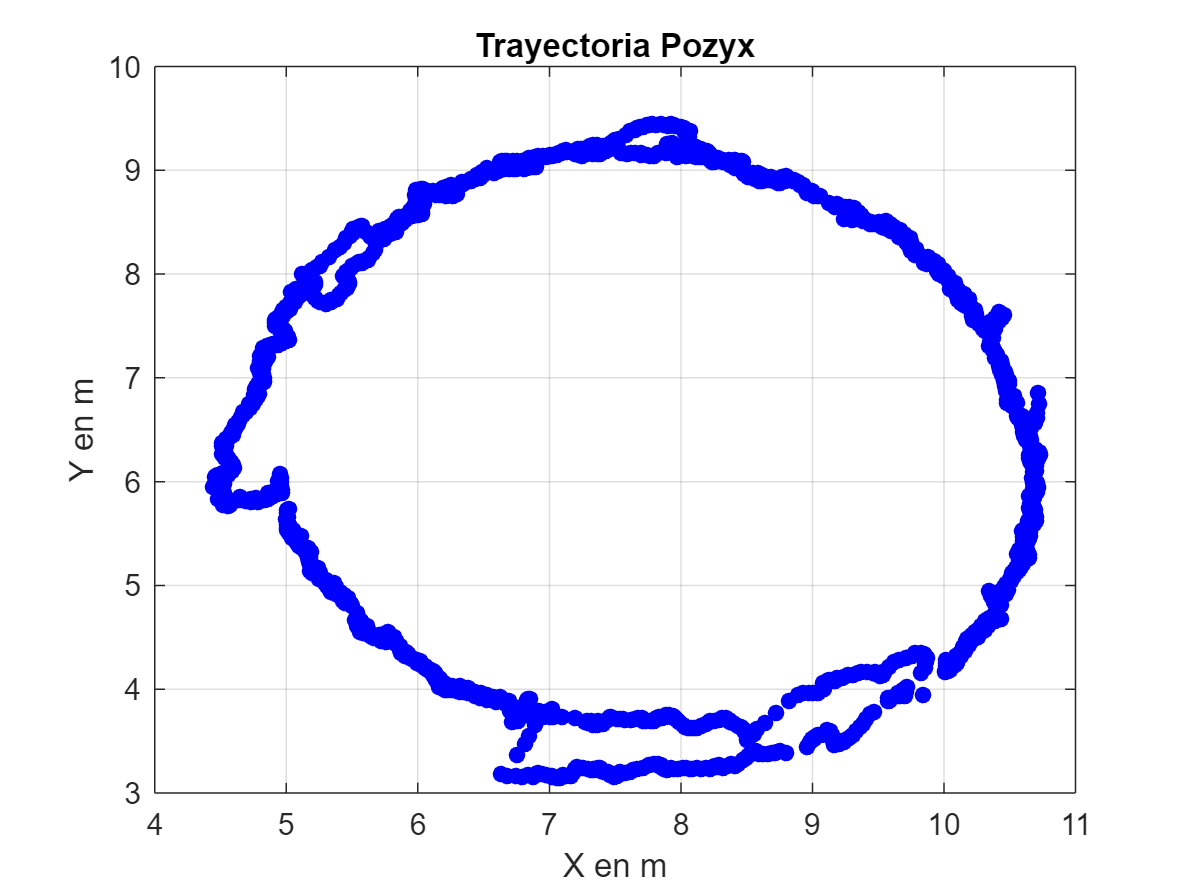


%-----------------------------
% Plot de la trayectoria Pozyx
%-----------------------------
figure;
plot(pozyx.position.x, pozyx.position.y,'o','color',[0 0 1],'MarkerFaceColor',[0 0 1],'MarkerSize',5);
title('Trayectoria Pozyx');
xlabel('X en m');
ylabel('Y en m');
grid on;

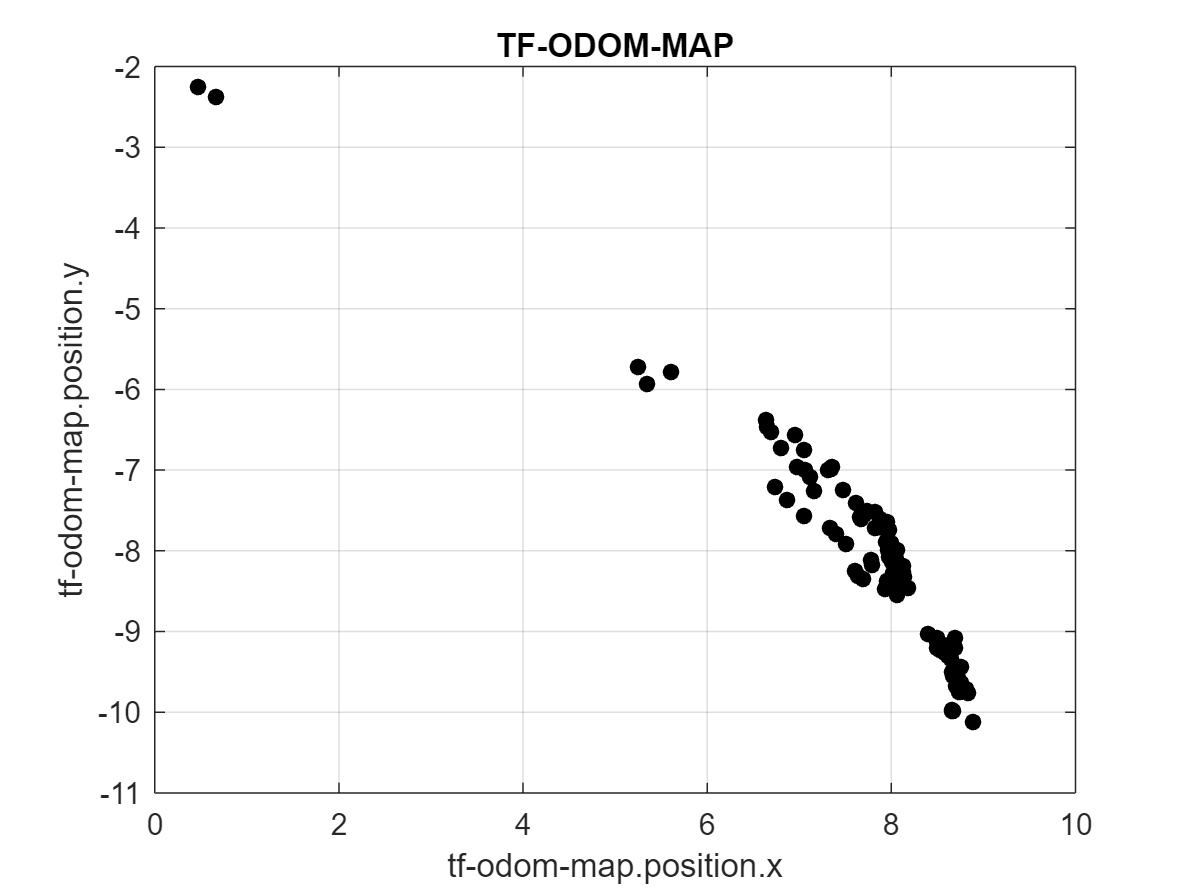


%----------------------------------------------------------
% Plot de tf_odom_map.position.x y tf_odom_map.position.y
%----------------------------------------------------------
figure;
plot(tf_odom_map.position.x,tf_odom_map.position.y,'o','color',[0 0 0],'MarkerFaceColor',[0 0 0],'MarkerSize',5);
title('TF-ODOM-MAP');
xlabel('tf-odom-map.position.x');
ylabel('tf-odom-map.position.y');
grid on;

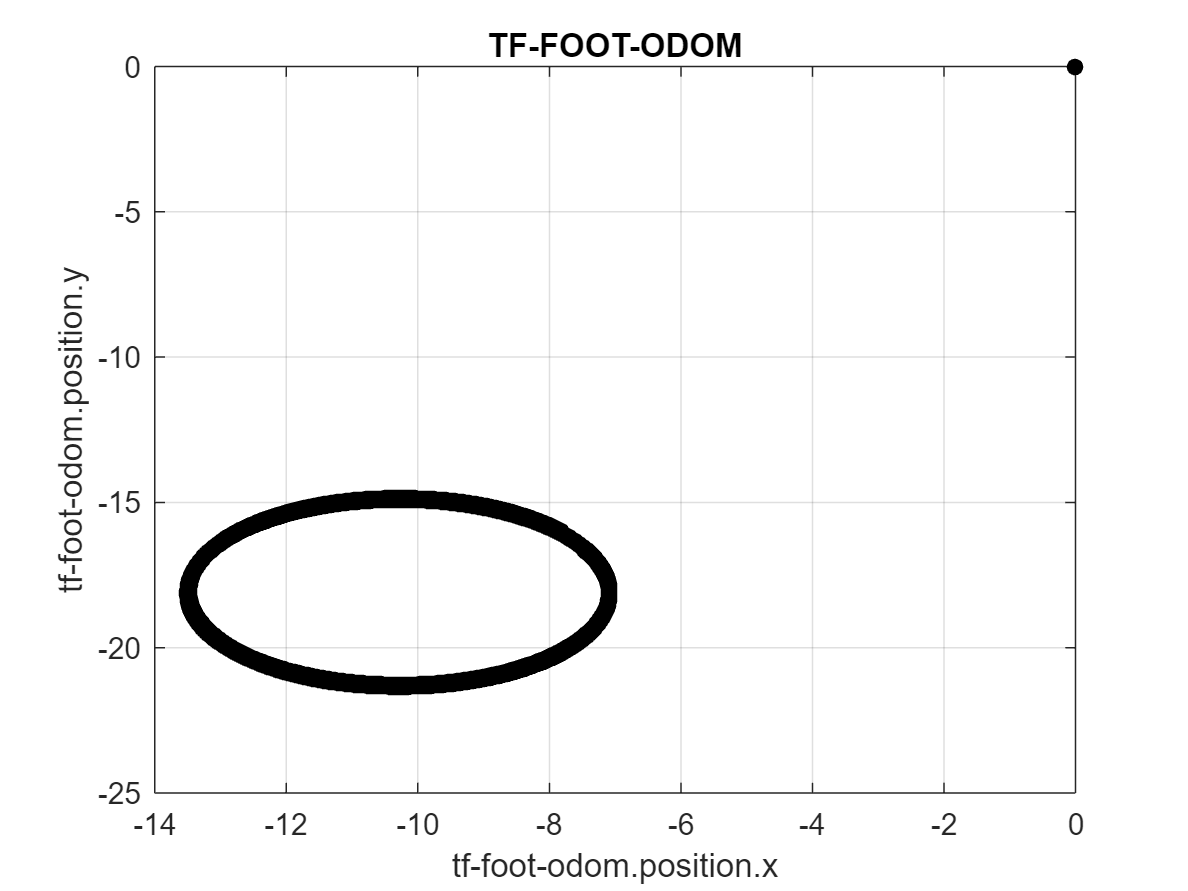


%----------------------------------------------------------
% Plot de tf_foot_odom.position.x y tf_foot_odom.position.y
%----------------------------------------------------------
figure;
j=1;
plot(tf_foot_odom.position.x,tf_foot_odom.position.y,'o','color',[0 0 0],'MarkerFaceColor',[0 0 0],'MarkerSize',5);
title('TF-FOOT-ODOM');
xlabel('tf-foot-odom.position.x');
ylabel('tf-foot-odom.position.y');
grid on;

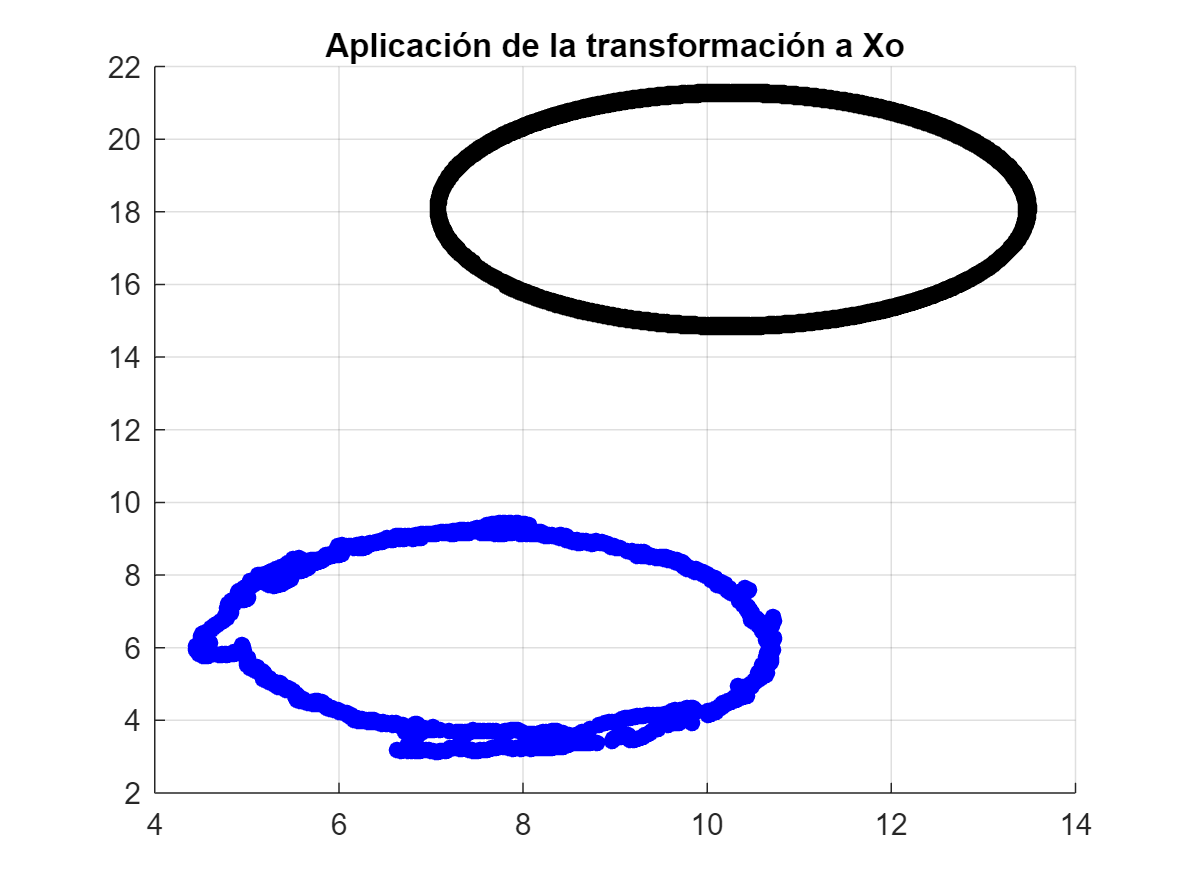


%---------------------------------------
% Plot de transformación matricial de Xo
%---------------------------------------
vogui_x = transform(:,1);
vogui_y = transform(:,2);
vogui_t = transform(:,4);

flag = 0;
index_ceros = find(vogui_x == 0);
for i=1:size(vogui_x,1)
    for j=1:size(index_ceros,1)
        if(i==index_ceros(j))
            flag = 1;
        end
    end
    if(flag == 0)
        vogui_x_final(i) = vogui_x(i);
        vogui_y_final(i) = vogui_y(i);
        vogui_t_final(i) = vogui_t(i);
    else
        vogui_x_final(i) = 0;
        vogui_y_final(i) = 0;
        vogui_t_final(i) = 0;
    end
    flag = 0;
end
vogui_x_final = vogui_x_final(vogui_x_final ~= 0)';
vogui_y_final = vogui_y_final(vogui_y_final ~= 0)';
vogui_t_final = vogui_t_final(vogui_t_final ~= 0);
vogui_t_final = [0 vogui_t_final]';


figure;
hold on;
plot(vogui_x_final,vogui_y_final,'o','color',[0 0 0],'MarkerFaceColor',[0 0 0],'MarkerSize',5);
plot(pozyx.position.x, pozyx.position.y,'o','color',[0 0 1],'MarkerFaceColor',[0 0 1],'MarkerSize',5);
title('Aplicación de la transformación a Xo');
grid on;


j=1;

for i=0:0.1:(vogui_t_final(end)-0.1)
    pozyx_index_time=find(pozyx_time==i);
    vogui_index_time=find(vogui_t_final==i);
    
    if (size(pozyx_index_time,1)~=0 && size(vogui_index_time,1)~=0)
        pozyx_index=pozyx_index_time(end);
        vogui_index=vogui_index_time(end);
        
        pozyx_compare(j,1)=pozyx.position.x(pozyx_index);
        pozyx_compare(j,2)=pozyx.position.y(pozyx_index);
        pozyx_compare(j,3)=pozyx_time(pozyx_index);
        
        vogui_compare(j,1)=vogui_x_final(vogui_index);
        vogui_compare(j,2)=vogui_y_final(vogui_index);
        vogui_compare(j,3)=vogui_t_final(vogui_index);
        
        
        j=j+1;
    end
end



VOGUI_FINAL = vogui_compare;
POZYX_FINAL = pozyx_compare;

VOGUI_FINAL(:,1) = VOGUI_FINAL(:,1)-2.5411;
VOGUI_FINAL(:,2) = VOGUI_FINAL(:,2)-12.0488;



figure;
hold on;
grid on;
xlim([4 11]);
ylim([2 10]);

X_POZ = POZYX_FINAL(150:end,1);
Y_POZ = POZYX_FINAL(150:end,2);
T_POZ = POZYX_FINAL(150:end,3)

T_POZ =    23.0000
   23.1000
   23.3000
   23.5000
   23.6000
   23.8000
   24.0000
   24.1000
   24.3000
   24.5000


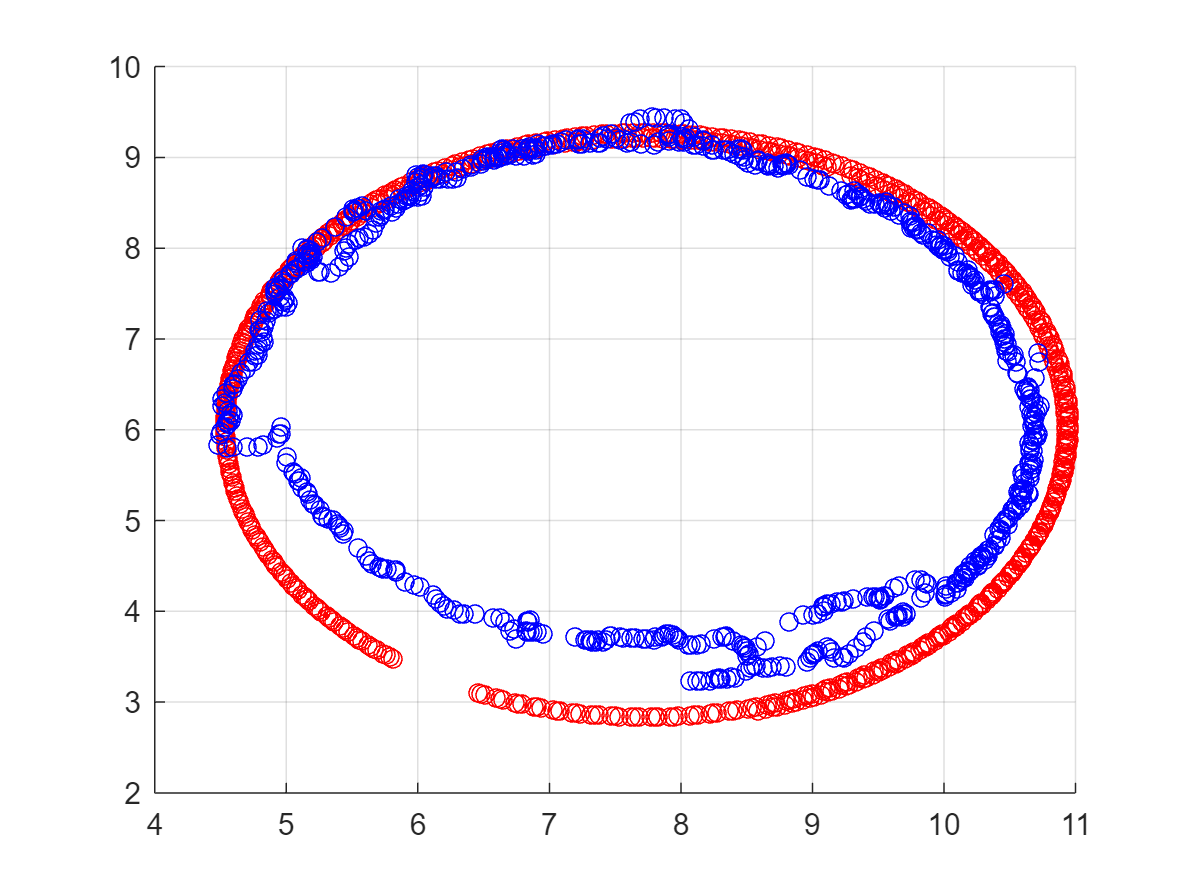


X_VOG = VOGUI_FINAL(58:end,1);
Y_VOG = VOGUI_FINAL(58:end,2);
T_VOG = VOGUI_FINAL(58:end,3);

new_vogui(:,1) = X_VOG(1:710);
new_vogui(:,2) = Y_VOG(1:710);
new_vogui(:,3) = T_VOG(1:710);

new_pozyx(:,1) = X_POZ;
new_pozyx(:,2) = Y_POZ;
new_pozyx(:,3) = T_POZ;
new_pozyx(:,3) = new_pozyx(:,3)-new_pozyx(1,3);

plot(new_vogui(:,1), new_vogui(:,2), 'o', 'color', [1 0 0]);
plot(new_pozyx(:,1), new_pozyx(:,2), 'o', 'color', [0 0 1]);
hold off;


%Error de los sistemas en X e Y
error_pozyx=new_vogui(:,1:2)-new_pozyx(:,1:2);
error_pozyx(:,3) = new_pozyx(:,3);

%Distancias euclideas entre puntos
for i=1:size(error_pozyx,1)
    p1=[new_pozyx(i,1) new_pozyx(i,2)];
    p2=[new_vogui(i,1) new_vogui(i,2)];
    norm_pozyx(i)=norm(p1-p2);
    RMSE(i) = sqrt(mean(norm_pozyx(i).^2));
end

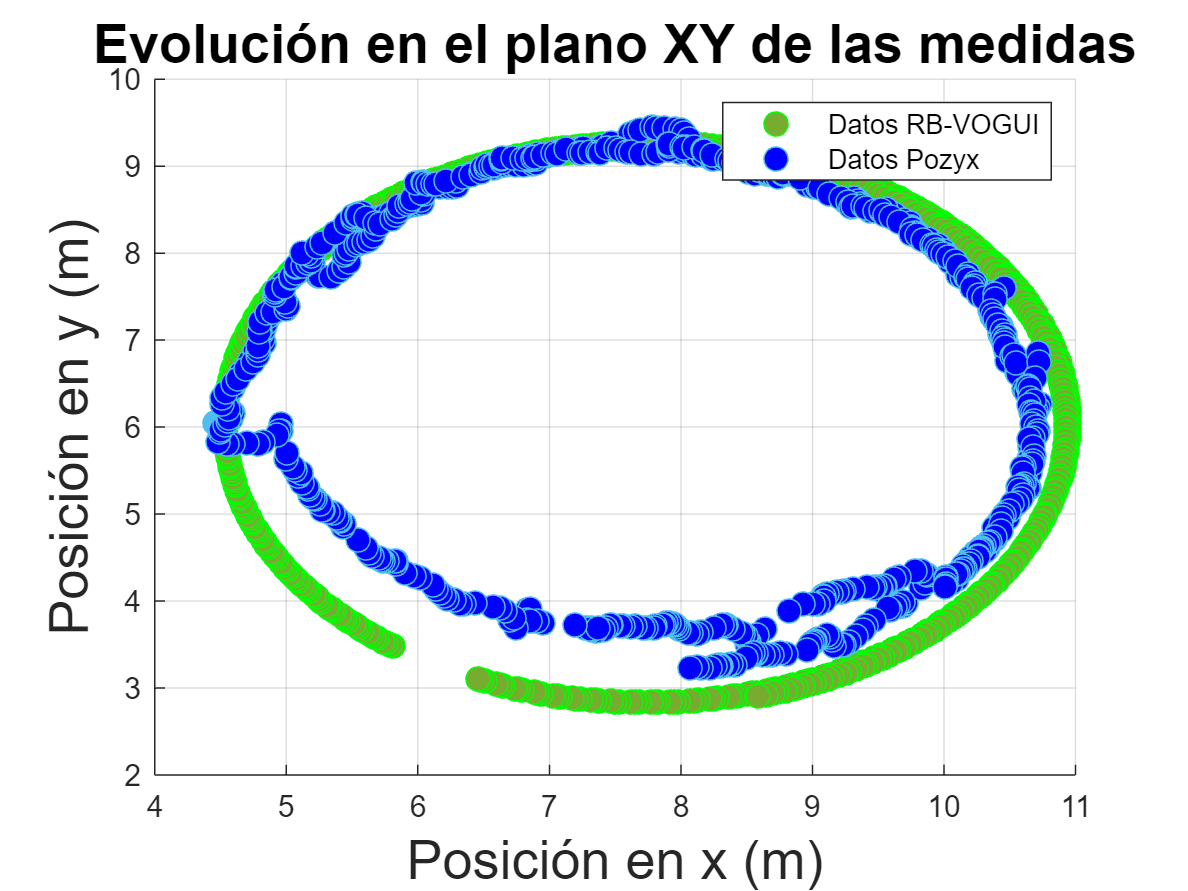

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Gráfico de la medida Pozyx
%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
hold on;
grid on;
plot(new_vogui(:,1),new_vogui(:,2),'o','color',[0 1 0],'MarkerFaceColor',[0.4660 0.6740 0.1880],'MarkerSize',8);
plot(POZYX_FINAL(:,1),POZYX_FINAL(:,2),'o','color',[0.3010 0.7450 0.9330],'MarkerFaceColor',[0 0 1],'MarkerSize',8);
title('Evolución en el plano XY de las medidas', 'FontSize', 18);
xlabel('Posición en x (m)', 'FontSize', 18);
ylabel('Posición en y (m)', 'FontSize', 18);
legend('Datos RB-VOGUI', 'Datos Pozyx');

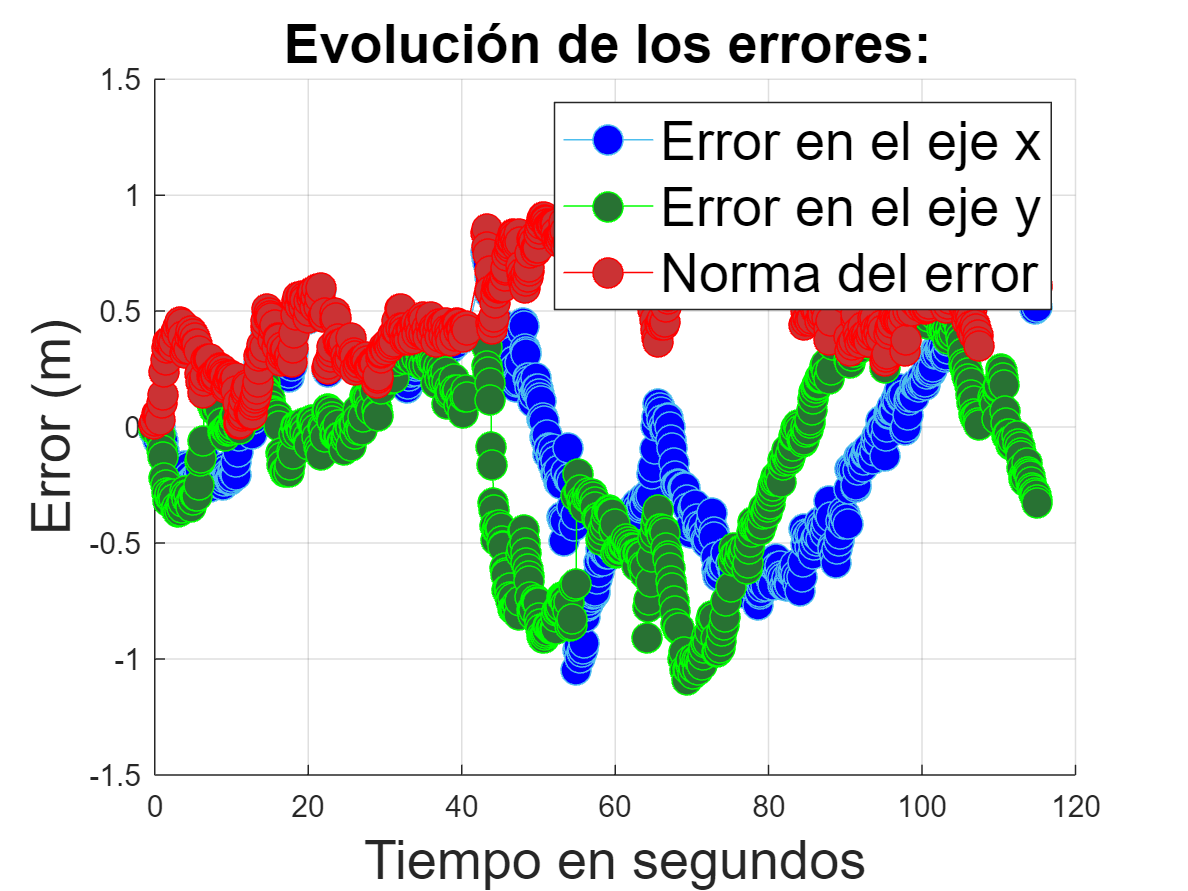


%%%%%%%%%%%%%%%%%%%%%%%  
%Gráfico de los errores
%%%%%%%%%%%%%%%%%%%%%%%
figure
hold on;
plot(new_pozyx(:,3), error_pozyx(:,1), '-o', 'color', [0.3010 0.7450 0.9330], 'MarkerFaceColor',[0 0 1],'MarkerSize',10);
plot(new_pozyx(:,3), error_pozyx(:,2), '-o', 'color',[0 1 0], 'MarkerFaceColor',[40/255 114/255 51/255],'MarkerSize',10);
plot(new_pozyx(:,3), norm_pozyx, '-o', 'color', [1 0 0], 'MarkerFaceColor',[203/255 50/255 52/255],'MarkerSize',10);
grid on;
title('Evolución de los errores: ', 'FontSize', 18);
xlabel('Tiempo en segundos', 'FontSize', 18);
ylabel('Error (m)', 'FontSize', 18);
legend('Error en el eje x', 'Error en el eje y', 'Norma del error', 'FontSize', 18);

% mean(abs(error_pozyx(:,1)))
% mean(abs(error_pozyx(:,2)))
% mean(norm_pozyx)
% sqrt(mean(norm_pozyx.^2))

max(abs(error_pozyx(:,1)))*100

ans = 104.7031

min(abs(error_pozyx(:,1)))*100

ans = 0.0091

max(abs(error_pozyx(:,2)))*100

ans = 108.8023

min(abs(error_pozyx(:,2)))*100

ans = 0.0117

max(norm_pozyx)*100

ans = 115.5999

min(norm_pozyx)*100

ans = 1.3156

sqrt(mean(norm_pozyx(:).^2))

ans = 0.6032